# Advanced Application Development: Zoo Hierarchy App

This example presents an example of an advanced app developed using Widgets Toolbox. The app combines several advanced concepts that help to optimize efficient development workflows and ensure the app is scalable and testable. The concepts used include:

- [Model-View-Controller Architecture](matlab:open('..\doc\UsingModelViewControllerClasses.html'))

- [Contextual View Widget](matlab:open('.\ContextualViewWidget.mlx'))

- [Reusable Superclasses for Hand-Code Apps](matlab:open('..\doc\AppSuperclasses.html'))

## App Example: Zoo Hierarchy

While MATLAB apps serve a wide variety of needs, a frequent app requirement involves viewing and manipulating a hierarchy data. The Zoo Hierarchy example app (Figure 1) has been designed specifically to provide a simplistic and understandable example for learning how to implement data hierarchy in a modular and programmatically written MATLAB app. This app manages data from a top level, in this case being the entirety of a zoo, down to the lowest level, the individual animals residing there.

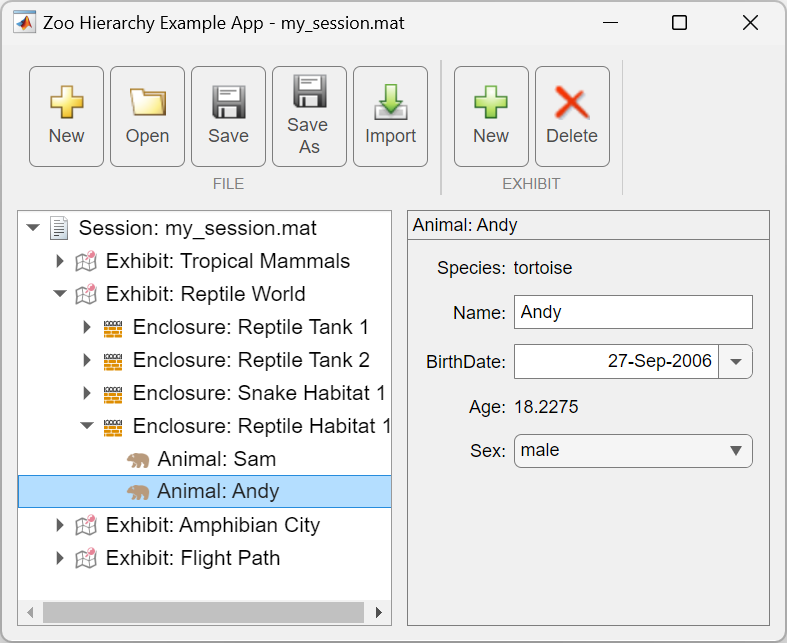

*Figure 1. The zoo hierarchy example app.*

## Running the Example

Run the example by calling the application's launcher:

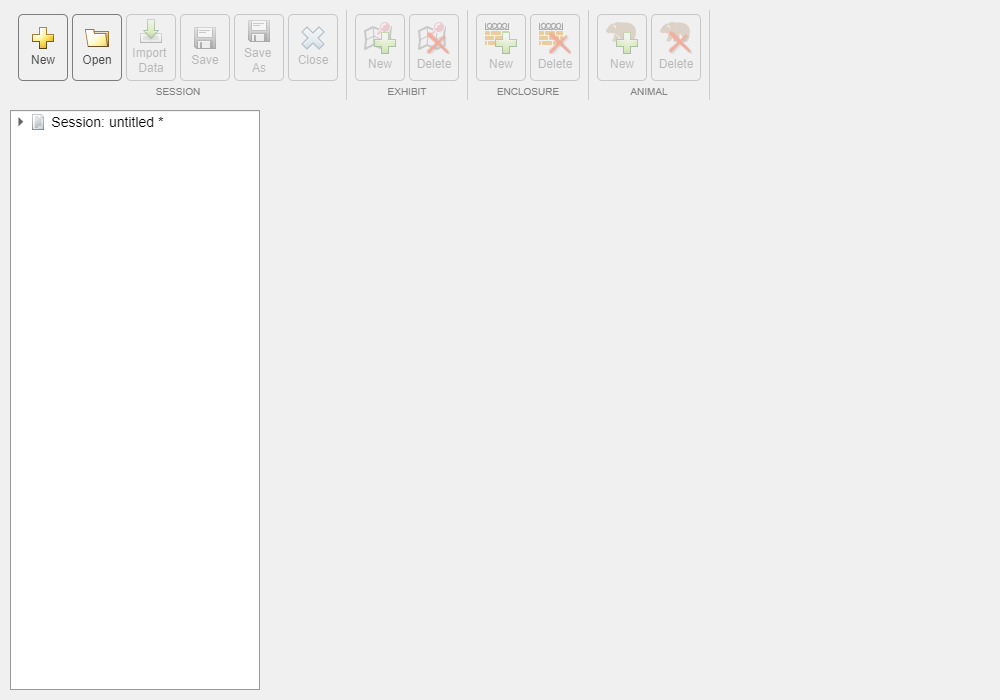

app = WidgetsZooAppLauncher;

Note that this launcher will pre-populate the app with a sample dataset. The optional output argument `app` provides a handle reference to the app. It is an instance of class [zooexample`.app.ZooHierarchy`](matlab:open('./+zooexample\+app\@ZooHierarchy\ZooHierarchy.m')).

Use the tree control on the left side of the app to navigate through the hierarchy, viewing the details on the right side:

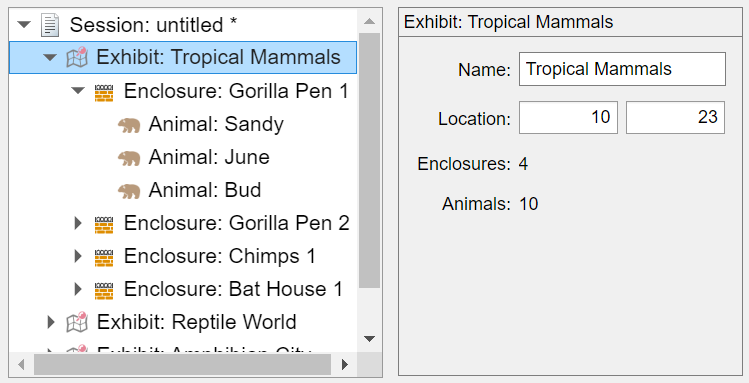

## How the Back-end Software Architecture was Implemented

### The Back-end Data Hierarchy

This app enables the user to view and edit data within a tree hierarchy. The tree has multiple different levels described below:

- Session: A single collection of data, also referred to as a "document", in this case corresponding to an entire zoo. A session may contain one or more Exhibit objects inside.

- Exhibit: A subset of a zoo, corresponding to one section or area. An exhibit may have one or more Enclosure objects within it.

- Enclosure: A specific cage enclosure, tank, etc. within an Exhibit. Multiple animals may stay within an enclosure.

- Animal: An individual animal within an Enclosure. This is the lowest level of the hierarchy.

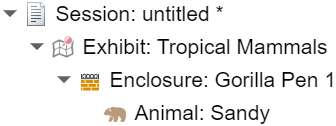

### Class Objects Representing the Data

Each of the items in the hierarchy was implemented using a MATLAB class object. These class objects were linked as a "parent / child" hierarchy. This is shown in Figure 2 below, a Unified Modeling Language (UML) class diagram:

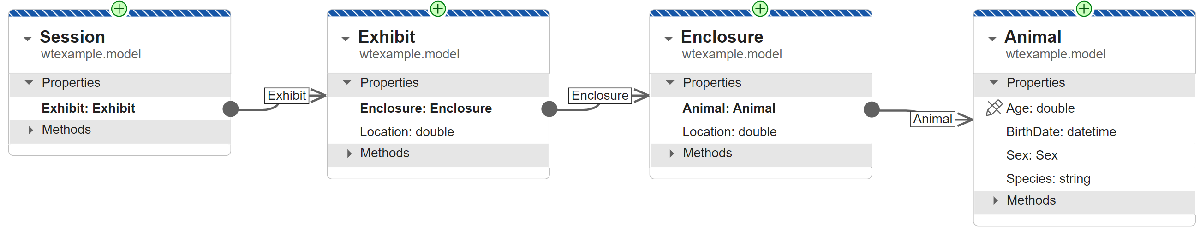

*Figure 2. UML class diagram showing data hierarchy for the zoo session.*

Each of the above class objects provides properties to store the relevant metadata for a given entity.  The first three objects also provide nested hierarchy where a property contains an array of other objects that belong to it. This type of object hierarchy is known as *composition* or *aggregation* from an object-oriented design perspective. 

### Implementation of the Back-end Model

These class objects were created to represent the *model* for the app, the entity that comprises the app's data, states, and algorithms.  As previously explained and shown in Figure 2, the model is implemented using four different class objects:

- [zooexample.model.Session](matlab:open('./+wt\+example\+model\Session.m'))

- [zooexample.model.Exhibit](matlab:open('./+wt\+example\+model\Exhibit.m'))

- [zooexample.model.Enclosure](matlab:open('./+wt\+example\+model\Enclosure.m'))

- [zooexample.model.Animal](matlab:open('./+wt\+example\+model\Animal.m'))

The backend model objects were implemented as handle classes, meaning the object that is passed by reference. This enabled the user's session to be in a consistent state. Multiple different view/controller modules within the app could reference these model classes simultaneously if needed and stay synchronized to the current state. 

(Please refer to this article for a discussion of handle vs. value classes: [Developing MATLAB Apps Using the Model-View-Controller Pattern - MATLAB & Simulink](https://www.mathworks.com/company/technical-articles/developing-matlab-apps-using-the-model-view-controller-pattern.html))

For convenience and code modularity reasons, reusable superclasses were developed to provide common functionality of these "model classes". The classes [BaseModel](matlab:open('..\+wt\+model\BaseModel.m')) and [BaseSession](matlab:open('..\+wt\+model\BaseSession.m')) provide the concrete classes (Session, Exhibit, Enclosure, Animal) with change notification from a public `PropertyChanged` event. This provides a simple mechanism for the view/controller classes displaying a model to listen to model changes and be alerted if a display update needs to happen.

The expanded UML hierarchy including superclasses is shown in Figure 3:

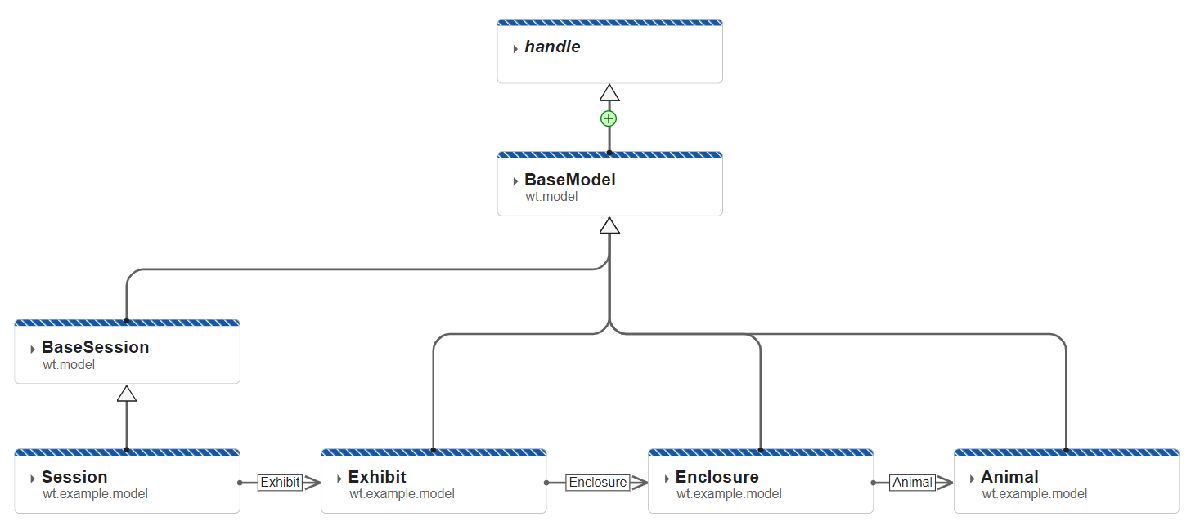

*Figure 3. UML class diagram showing superclass hierarchy, with the four concrete model classes at the bottom*

## How the Front-end Views and Controllers were Implemented to Display the Model Classes

### Hybrid View/Controller Components

In the case of this app, the view and controller functions are desired to be shown together, so hybrid view/controller classes were implemented for each of the four views. The app has four different types of views, one for each of the four model classes. Each of these four model classes has a corresponding view/controller component. These are shown in Figure 4:

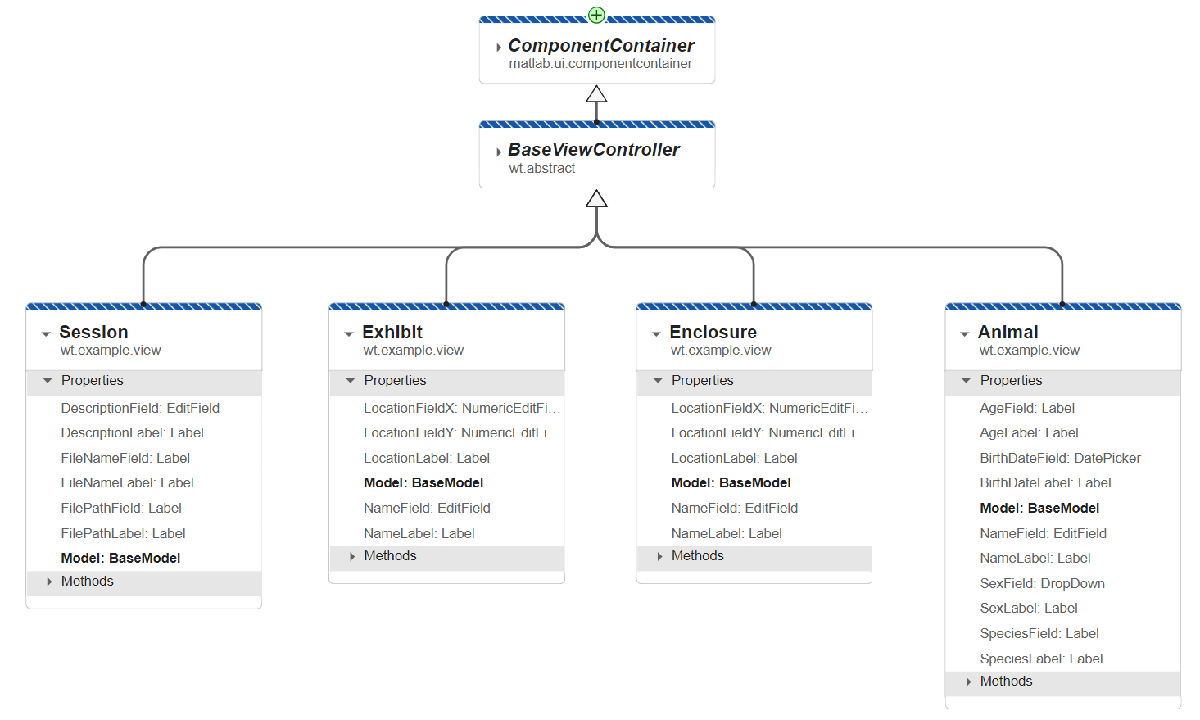

*Figure 4. UML class diagram showing (four lower boxes) the view/controller components that display their respective model classes*

#### Example

Aside from use in the app itself, these view/controller components are individual standalone and reusable modules. 

Here we can create and populate an Animal model class instance:

animalA = zooexample.model.Animal;
animalA.Species = "Lion";
animalA.Name = "Simba";
animalA.Sex = "male";
animalA.BirthDate = "March 9, 2017";
disp(animalA)

  Animal with properties:

      Species: "Lion"
    BirthDate: 09-Mar-2017
          Sex: male
          Age: 7.8600
         Name: "Simba"



Then, create an Animal view placed within a figure and provide it with the model to display:

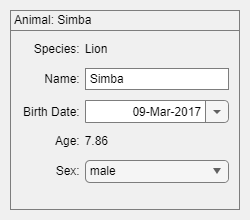

fig1 = uifigure("Position",[100 100 250 220]);
grid1 = uigridlayout(fig1,[1 1]);
view1 = zooexample.view.Animal(grid1, "Model", animalA);

This view is synchroniced with the model such that if you modify the model externally, the view will be notified and updates automatically:

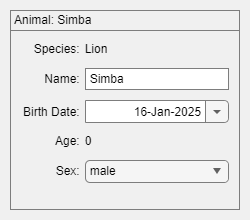

animalA.BirthDate = datetime("today");

The birthdate and age are updated to reflect the change.

## How the Overall App was Implemented

### App Superclasses

The top level of the Zoo Hierarchy App is a hand-coded class file. Its UML class diagram is shown in Figure 5:

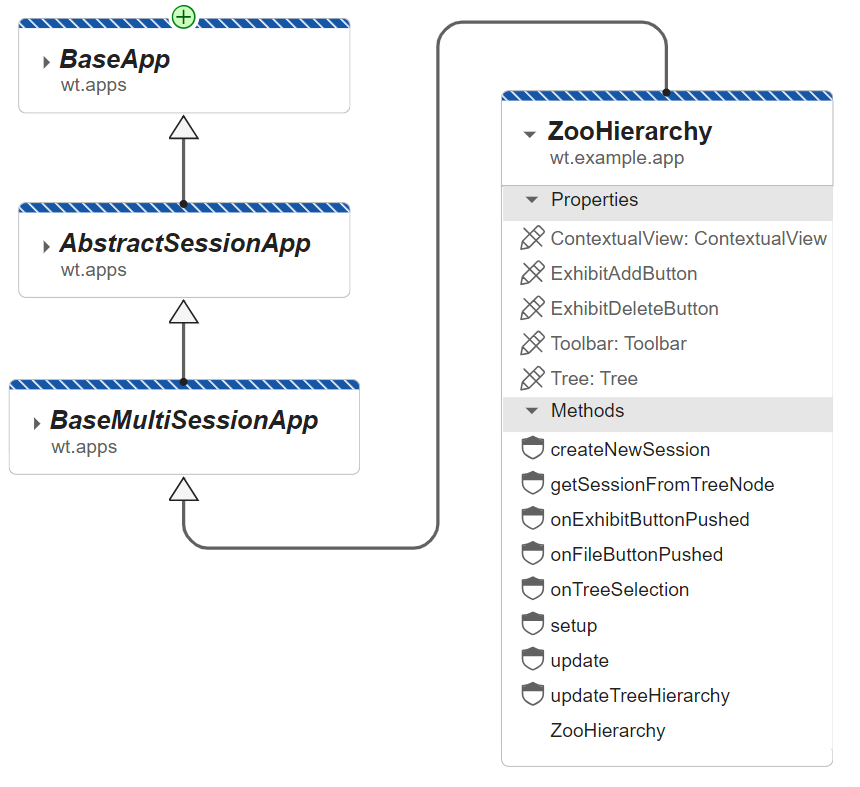

*Figure 5. UML class diagram showing the Zoo Hierarchy app and its superclasses*

The [`zooexample.app.ZooHierarchy` class](matlab:open('./+wt\+example\+app\@ZooHierarchy\ZooHierarchy.m')) implements the functionality unique to the ZooHierarchy main application, but leaves common functionalities to inherited and superclasses that are reusable for other applications. In addition, functionalities that not specific to the Zoo Hierarchy app and are commonly needed for other apps are implemented in superclasses that are inherited by the `ZooHierarchy` class. Superclass functionalities implemented in [`BaseApp`](matlab:open('..\+wt\+apps\BaseApp.m')), [`AbstractSessionApp`](matlab:open('..\+wt\+apps\AbstractSessionApp.m')), and [`BaseMultiSessionApp`](matlab:open('..\+wt\+apps\BaseMultiSessionApp.m')) include:

- Encapsulating and preparing the figure window.

- Management of user preferences, such as recent folders and initial window size on launch.

- Management of the user's session state (or "document") being used in the app.

- Save and load of these user sessions to a file.

- Listening to session changes to handle "dirty" state, prompting to save changes before closing as necessary.

For further information about these app superclasses, please see: [Advanced Application Development: Reusable Superclasses for Hand-Code Apps](matlab:open('..\doc\AppSuperclasses.mlx'))

### ZooHierarchy Main App Implementation

The [`zooexample.app.ZooHierarchy` class](matlab:open('./+wt\+example\+app\@ZooHierarchy\ZooHierarchy.m')) itself implements the upper toolbar, the left tree hierarchy, and the placement of contextual contents into the right pane. The actual content that gets placed in the right pane is implemented separately in the view/controller classes previously discussed.

At a high level, this class definition includes:

- Properties to store internal components.

- Creation and update of the graphical components.

- Callback functions for user controls implmented at this level.

- Helper functions to help manage the above items.

#### Properties to Store Internal Components

Internal components are stored in properties upon the app's setup task during creation. This enables them to be accessible during callbacks, updates, and other internal functions. Components within this top-level app include:

- The toolbar at the top, containing buttons for save/load session and other functions.

- The left-side tree for navigation.

- The [ContextualView](matlab:open('..\doc\ContextualViewWidget.mlx')) pane on the right for displaying a view of the selected tree node's data.

#### Creation and Update of Graphical Components

The application class implements methods that manage the graphical state:

- The `setup` method, responsible for creating the set of components and controls when the app is launched.

- The `update` method, responsible for updating main app level content when a model state change has been detected.

- updateTreeHierarchy is called by the `update` method when the tree hierarchy needs to be redrawn. This is implemented in a separete .m file within the @ZooHierarchy folder because it is a long and complex method. It parses the hierarchy of the app's `Session` property recursively and synchronizes the hierarchy of tree nodes to match the contents.

#### Callback Functions for User Controls

Several callbacks are implemented as methods of the `ZooHierarchy` class:

- `onFileButtonPushed` and `onExhibitButtonPushed` handle user interaction with the upper toolbar.

- `onTreeSelection` handles user interaction with the tree, triggering the appropriate right-side contextual pane to be launched. It also provides the relevant model reference for the given tree node. 

#### Context pane switching

The right side of the app contains a [`wt.ContextualView`](matlab:open('..\+wt\ContextualView.m')) widget. This widget provides a container for switching between multiple view/controller components. You can think of it as being similar to a tabpanel, however the contents are switched programmatically. For more information about this widget, please see [Contextual View Widget](matlab:open('..\doc\ContextualViewWidget.mlx')).

*Copyright 2025 The MathWorks, Inc.*